# Preliminaries: graphs, matrices and the direction convention

This notebook fixes the conventions used throughout the project and introduces the structural analysis that governs every model that follows.

Run `setup_paths` once per MATLAB session before any of these notebooks.

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

NDS opinion-dynamics library added to the path.
Project root: /Users/llp/Desktop/NDS_Project


## The direction convention, fixed once

Every matrix in this project follows one rule:

Equivalently, row i lists whom agent i listens to, which is why the rows are the objects that must sum to one.

The two books in the repository draw the arrows in opposite directions: Proskurnikov & Tempo point them along the flow of influence, Bullo points them from the advice seeker to the advisor. THE MATRIX IS THE SAME; only the picture differs. `plot_network` exposes this as an option so a figure can be matched to a published one without ever transposing the data.

net = make_example_french3();
disp(net.W)

    0.5000    0.5000         0
    0.3333    0.3333    0.3333
         0    0.5000    0.5000



disp(net.meta.convention)

A(i,j)>0 : agent i accords weight to agent j (row i = who i listens to)


## Building a network

`net_from_matrix` wraps raw weights into the structure used everywhere. It keeps BOTH the raw weights A and the row-stochastic W, because the continuous-time models use A (its row sums set the interaction rates) while the discrete-time models need W.

A = [0 1 0; 0 0 2; 3 0 0];
demo = net_from_matrix(A, 'Name', 'demo');
fprintf('raw row sums : %s\n', mat2str(sum(demo.A, 2).'));

raw row sums : [1 2 3]


fprintf('W row sums   : %s\n', mat2str(sum(demo.W, 2).'));

W row sums   : [1 1 1]


fprintf('L * 1        : %s\n', mat2str(round(demo.L * ones(3,1), 12).'));

L * 1        : [0 0 0]


## The structural report

`graph_report` computes the facts that decide convergence: strong components, which of them are CLOSED, their periods, and whether the graph is rooted.

Theorem 12 of the tutorial: the French-DeGroot model converges iff every closed strong component is aperiodic, and reaches consensus iff the graph is additionally rooted.

graph_report(net.W);

Graph report (3 agents)
  strong components : 1  (strongly connected)
    #1 [CLOSED] period=1 : [1 2 3]
  rooted            : yes
  roots             : [1 2 3]
  convergent        : yes
  reaches consensus : yes


## The standard topologies

These are the synthetic networks used throughout the project. Each one isolates a different structural phenomenon.

topologies = { ...
    make_ring(6),                          'directed ring (period 6)'; ...
    make_ring(6, 'Type', 'symmetric'),     'symmetric ring, n even (period 2)'; ...
    make_ring(7, 'Type', 'symmetric'),     'symmetric ring, n odd (aperiodic)'; ...
    make_ring(6, 'SelfWeight', 0.3),       'lazy ring (aperiodic)'; ...
    make_star(6, 'Type', 'hub-source'),    'star, hub is a stubborn root'; ...
    make_star(6, 'Type', 'bidirectional'), 'bidirectional star (period 2)'; ...
    make_path(6),                          'directed path (rooted, not strong)'; ...
    make_complete(6),                      'complete graph'; ...
    make_two_communities(3, 0),            'two communities, beta = 0'; ...
    make_two_communities(3, 0.2),          'two communities, beta = 0.2'};

fprintf('\n%-38s %6s %8s %9s %10s\n', 'network', 'comps', 'rooted', 'converge', 'consensus');


network                                 comps   rooted  converge  consensus


for k = 1:size(topologies, 1)
    r = graph_report(topologies{k, 1}.W);
    fprintf('%-38s %6d %8d %9d %10d\n', topologies{k, 2}, ...
        r.nComponents, r.isRooted, r.isConvergent, r.reachesConsensus);
end

directed ring (period 6)                    1        1         0          0
symmetric ring, n even (period 2)           1        1         0          0
symmetric ring, n odd (aperiodic)           1        1         1          1
lazy ring (aperiodic)                       1        1         1          1
star, hub is a stubborn root                6        1         1          1
bidirectional star (period 2)               1        1         0          0
directed path (rooted, not strong)          6        1         1          1
complete graph                              1        1         1          1
two communities, beta = 0                   2        0         1          0
two communities, beta = 0.2                 1        1         1          1


## Reading the theorems off the spectrum

The convergence conditions become visible in one picture. A periodic graph of period h shows h eigenvalues spread evenly around the unit circle -- and that is exactly why its opinions oscillate.

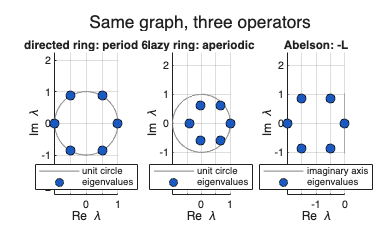

figure;
tl = tiledlayout(1, 3);
plot_spectrum(make_ring(6).W,                   'Axes', nexttile(tl), 'Title', 'directed ring: period 6');
plot_spectrum(make_ring(6, 'SelfWeight', 0.3).W,'Axes', nexttile(tl), 'Title', 'lazy ring: aperiodic');
plot_spectrum(-make_ring(6).L, 'Domain', 'continuous', ...
    'Axes', nexttile(tl), 'Title', 'Abelson: -L');
title(tl, 'Same graph, three operators');

## The real network

Krackhardt's advice network among 21 managers, recovered from the primary source and validated against the degree sequence published by Sims & Gilles. It is REDUCIBLE but rooted and aperiodic, so it reaches consensus.

kr = load_krackhardt();
graph_report(kr.W);

Graph report (21 agents)
  strong components : 5
    #1 period=0 : 17
    #2 period=0 : 16
    #3 period=0 : 13
    #4 period=0 : 6
    #5 [CLOSED] period=1 : [1 2 3 4 5 7 8 9 10 11 12 14 15 18 19 20 21]
  rooted            : yes
  roots             : [1 2 3 4 5 7 8 9 10 11 12 14 15 18 19 20 21]
  convergent        : yes
  reaches consensus : yes


fprintf('\nprovenance : %s\n', kr.meta.source);


provenance : Krackhardt (1987), Social Networks 9(2):109-134, Appendix A, p. 129


fprintf('aggregation: %s\n', kr.meta.aggregation);

aggregation: LAS (Locally Aggregated Structure)
